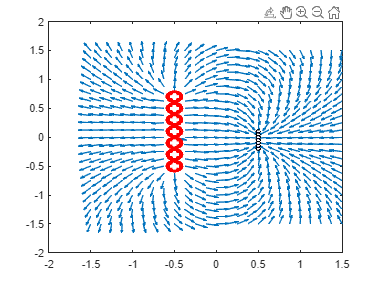

clear;
close all;
clc;

%Constantes
k = 9*1e+9;

x0 = -0.5;
x1 = 0.5;

h = 0.2;
h2 = 0.05;

y1 = -0.5;
y2 = -0.2;

q = 2*1e-6;
q2 = -2*1e-6;

radio = h/2;
radio2 = h2/2;

%Espacio de graficación
x = linspace(-1.5,1.5,25);
y = linspace(-1.5,1.5,25);
[xx,yy] = meshgrid(x,y);

Ex = zeros(size(xx));
Ey = zeros(size(yy));

%Campo electrico positivo
for i = 1:7
    y0 = y1 + h*(i-1);
    R = sqrt((xx - x0).^2 + (yy - y0).^2);

    Ex = Ex + k*q*(xx-x0)./R.^3;
    Ey = Ey + k*q*(yy-y0)./R.^3;
end

%Campo electrico negativo
for i = 1:7
    y0 = y2 + h2*(i-1);
    R = sqrt((xx - x1).^2 + (yy - y0).^2);

    Ex = Ex + k*q2*(xx-x1)./R.^3;
    Ey = Ey + k*q2*(yy-y0)./R.^3;
end

mag = sqrt((Ex.^2)+(Ey.^2));

quiver(xx, yy, Ex./mag,Ey./mag)
hold on

%Graficar y crear cargas
for i = 1:7
    y0 = y1 + h *(i-1);
    pos = [x0-radio, y0-radio, 2*radio, 2*radio];
    pos2 = [x0-radio/2, y0-radio/6, radio, radio/3];
    pos3 = [x0-radio/6, y0-radio/2, radio/3, radio];
    rectangle('Position',pos,'Curvature',[1,1],'FaceColor','r','EdgeColor','r')
    rectangle('Position',pos2, 'Curvature',[0.2,0.2],'FaceColor','w','EdgeColor',[1 1 1]);
    rectangle('Position',pos3, 'Curvature',[0.2,0.2],'FaceColor','w','EdgeColor',[1 1 1]);
end

for i = 1:7
    y0 = y2 + h2 *(i-1);
    pos = [x1-radio2, y0-radio2, 2*radio2, 2*radio2];
    pos2 = [x1-radio2/2, y0-radio2/6, radio2, radio2/3];
    rectangle("Position",pos,"Curvature",[1 1],"FaceColor","b");
    rectangle('Position',pos2, 'Curvature',[0.2,0.2],'FaceColor','w','EdgeColor',[1 1 1]);
end
hold off